h = 6.626e-34;
probe_line_temp = .03; % effective temp of cavity around resonant freq - decides number of cavity photons
% around the resonance
amp_noise_photons_at_input_to_chain = 50;
kb = 1.38e-23;
res_freq = 5.7777e9;
kappa_ext = 0.8944e6;
kappa_int = 1.391e6;
kappa_tot = kappa_ext + kappa_int;
kerr = 0.333e6;
% kerr = kappa_tot/100;
flux_pump_to_damping_rate_ratio = 28;
flux_pump = flux_pump_to_damping_rate_ratio * kappa_tot;
pump_detuning = -11e6;
gain_amp_chain = 70.388;
% gain_amp_chain = 90; %dB TWPA 6.767GHz, -2.25dBm
rotating_frame_freq = (res_freq - pump_detuning)

rotating_frame_freq = 5.7887e+09

pump_freq = 2 * (res_freq - pump_detuning);
sa_span = 3e6;
sa_number_points = 100001;
res_BW = 5.1e3;
freqs_around_pump_over_2 = linspace(-sa_span/2, sa_span/2, sa_number_points);

%%% classical parametric oscillation oscillation amp %%%
if pump_detuning > sqrt(flux_pump^2 - kappa_tot^2/4)
    cavity_amp = 0 % units of photon number
elseif sqrt(flux_pump^2 - kappa_tot^2/4) > pump_detuning
    cavity_amp = 1/kerr *(-pump_detuning + sqrt(flux_pump^2 - kappa_tot^2/4)) %units of photon number
else 
    cavity_amp = 0
end

cavity_amp = 225.1682

%%% quantum fluctuation quantities
ksi_tilde = pump_detuning + 2*kerr*cavity_amp

ksi_tilde = 1.3896e+08

flux_pump_tilde = flux_pump + kerr*cavity_amp

flux_pump_tilde = 1.3897e+08

determinant = (kappa_tot/2 - 1i.*freqs_around_pump_over_2).^2 + ksi_tilde.^2 - abs(flux_pump_tilde).^2;
matrix_1_1 = determinant + 1i*kappa_ext*(ksi_tilde + freqs_around_pump_over_2) - kappa_ext*kappa_tot/2;
matrix_1_2 = 1i*kappa_ext*flux_pump_tilde;

See Wustmann notes page 23

%%%% power spectrum
cavity_thermal_occupation_number = 1/ (exp(h*res_freq/kb/probe_line_temp) - 1);
psd_at_omega = h*res_freq/4/pi./(abs(determinant)).^2 .*(2*abs(matrix_1_2).^2 + abs(matrix_1_1).^2 ...
    + abs(flip(matrix_1_1)).^2)* (4*cavity_thermal_occupation_number +  2);
added_noise_photons_at_amp_input = ones(size(freqs_around_pump_over_2)) .* amp_noise_photons_at_input_to_chain;
added_noise_power_at_amp_input = ones(size(freqs_around_pump_over_2)) .* amp_noise_photons_at_input_to_chain * h .* ...
    (freqs_around_pump_over_2 + res_freq + pump_detuning);
classical_cavity_amplitude = zeros(size(psd_at_omega));
classical_cavity_amplitude(freqs_around_pump_over_2 == 0) = cavity_amp * h * res_freq;
classical_cavity_output = classical_cavity_amplitude * kappa_ext;
total_output_psd_probe_line = psd_at_omega + classical_cavity_output;
total_output_psd_with_noise_probe_line = total_output_psd_probe_line + added_noise_power_at_amp_input;
total_output_psd_at_SA = total_output_psd_with_noise_probe_line * 10^(gain_amp_chain/10);
total_output_psd_at_SA_dBm = 10*log10(total_output_psd_at_SA / 1e-3);
amp_noise_psd_at_SA = added_noise_power_at_amp_input *10^(gain_amp_chain/10);
amp_noise_psd_at_SA_dBm  = 10*log10(amp_noise_psd_at_SA/1e-3);
%%% convert to power spectrum using RBW
total_output_spectrum_at_SA_dBm = total_output_psd_at_SA_dBm + 10*log10(res_BW);
total_output_noise_spectrum_at_SA_dBm = amp_noise_psd_at_SA_dBm + 10*log10(res_BW);

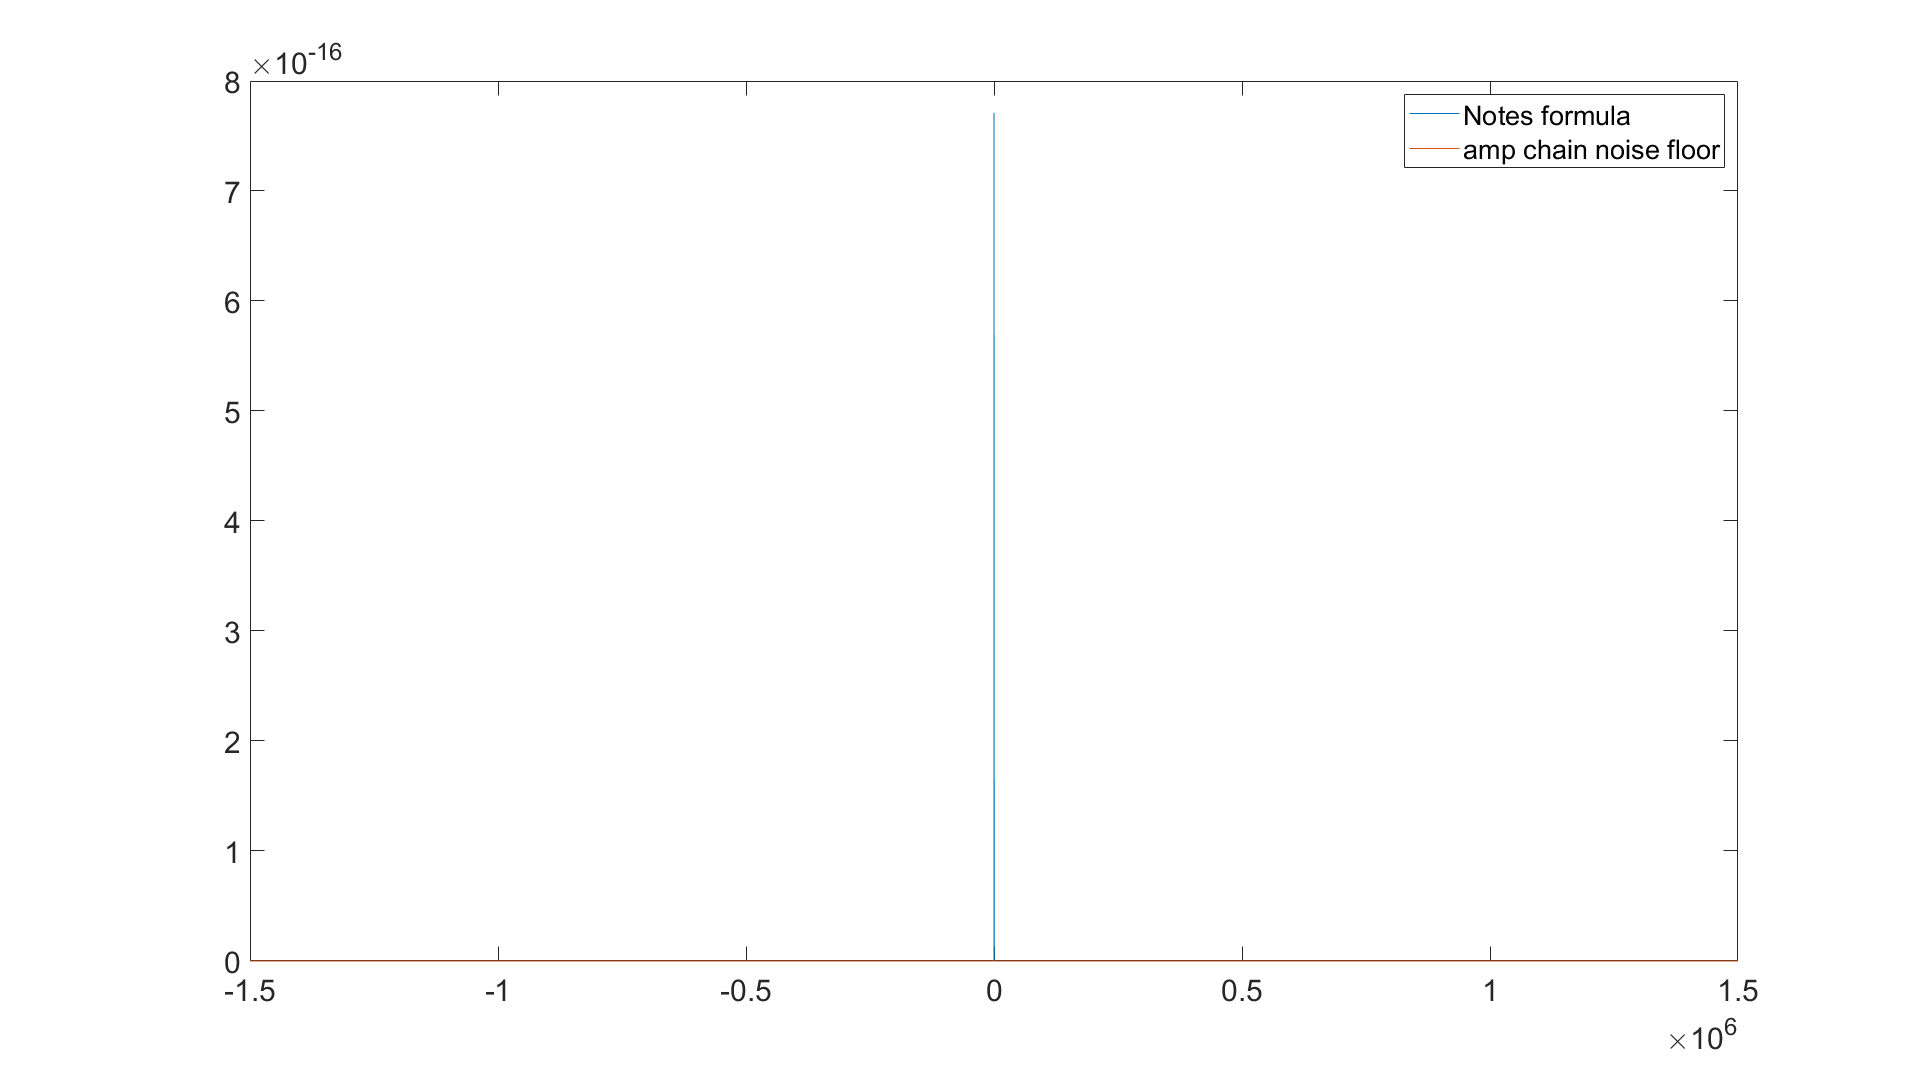

figure
plot(freqs_around_pump_over_2, total_output_psd_probe_line , 'DisplayName','Notes formula')
hold on
plot(freqs_around_pump_over_2, added_noise_power_at_amp_input, 'DisplayName', 'amp chain noise floor')
legend show

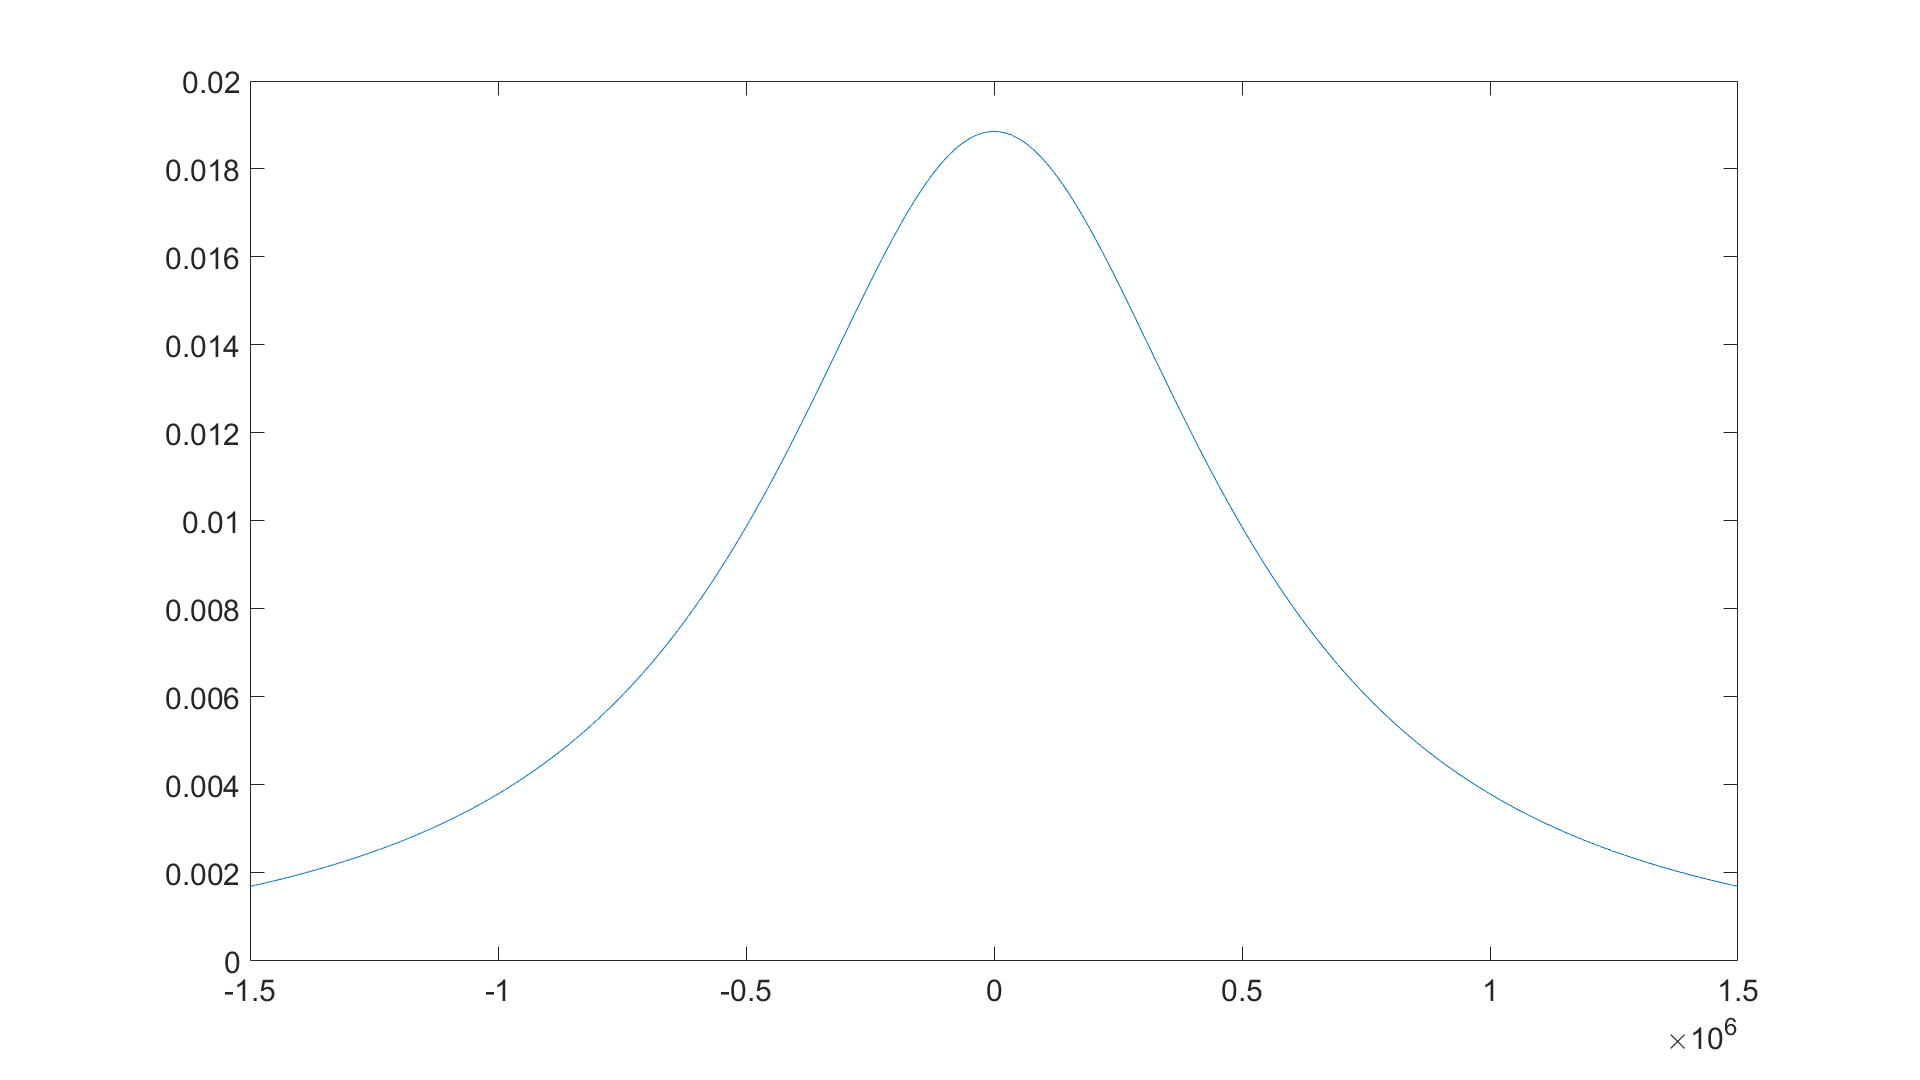

figure
plot(freqs_around_pump_over_2, kappa_tot *flux_pump_tilde^2./abs(determinant).^2, 'DisplayName', 'intracavity photons Wustmann formula')
hold on

plot(freqs_around_pump_over_2, intracavity_noise_photons,'DisplayName', 'intracavity noise photons notes')

Unrecognized function or variable 'intracavity_noise_photons'.

legend show

figure
plot(freqs_around_pump_over_2, flux_pump_tilde^2 * kappa_tot^2./(abs(determinant)).^2, 'DisplayName', 'Wustmann formula')
hold on
plot(freqs_around_pump_over_2, added_noise_photons_at_amp_input, 'DisplayName','added noise')
plot(freqs_around_pump_over_2, psd_at_omega/h/res_freq, 'DisplayName', 'output photons notes formula')
legend show

figure
% plot(freqs_around_pump_over_2, 2*abs(matrix_1_2).^2 + matrix_1_1 .* ...
%     flip(conj(matrix_1_1)) + flip(matrix_1_1).*conj(matrix_1_1))
% hold on
plot(freqs_around_pump_over_2, 1./abs(determinant).^2)

figure
% plot(freqs_around_pump_over_2, total_output_psd_at_SA_dBm, 'DisplayName', 'total output power at SA with RBW 1Hz')
hold on
% plot(freqs_around_pump_over_2, amp_noise_psd_at_SA_dBm, 'DisplayName', 'Amp noise at SA with RBW 1Hz')
plot(freqs_around_pump_over_2, total_output_spectrum_at_SA_dBm, 'DisplayName', ['total output power at SA with RBW = ' num2str(res_BW/1e3) 'kHz'])
plot(freqs_around_pump_over_2, total_output_noise_spectrum_at_SA_dBm, 'DisplayName', ['Amp noise at SA with RBW = ' num2str(res_BW/1e3) 'kHz'])
legend show